# Visualize Elementary Flux Modes from *E. coli* model

## Author(s): Chaitra Sarathy, Martina Kutmon (Maastricht University, The Netherlands)

## Reviewer(s): 

*Include those who have reviewed the tutorial, and are therefore partly responsible for picking up errors or omissions.*

## INTRODUCTION

Elementary Flux Modes (EFMs) are a tool for constraint-based modelling and metabolic network analysis. However, systematic and automated visualization of EFMs, capable of integrating various data types is still a challenge. This tutorial is part of the study by Sarathy et al. (2019, in preparation), "An integrative workflow to visualize Elementary Flux Modes in genome-scale metabolic models". 

This workflow can be used to visualize EFMs calculated using any currently available methods. Inputs for the workflow are: (1) the text file containing EFMs and (2) the genome-scale metabolic model used for generating EFMs. Additionally, omics data can be used to select one (or more) EFM(s) for visualization among the vast number of EFMs that usually results from EFM calculation. Sarathy et al. (2019, in preparation) demonstrate two examples of such a selection procedure (a) Yield Analysis and (b) EFM Enrichment with EFMs calculated from genome-scale metabolic models, (1) iAF1260 (E. coli) [1] and (2) Recon 2.2 (Human) [2]. 

Each use case is explained with a tutorial. This tutorial corresponds to the first use case and it describes how to analyze and visualize EFMs from the *E. coli *model iAF1260*. *The aim is to apply the workflow on a small-scale model and it can be used as a means to study acetate overflow metabolism in E. coli. EFMs were generated for glucose uptake reaction. For details on how EFMs were generated, please refer the citation section at [https://github.com/macsbio/efmviz](https://github.com/macsbio/efmviz)

The steps in the workflow include:

        **A. Specifying Inputs: **

        i. Import input data: file containing EFMs (.txt), model file (.mat), file containing relative fluxes for active reactions in EFM (.txt)

        (Note: relative fluxes are usually calculated during EFM generation. if this file is not available, fluxomics data can also be used instead)

       ** B. EFM Selection**

        i. Filter EFMs containing a reaction of interest

        ii. Calculate yields using the fluxes imported in step A

        iii. Select EFMs with desired value of yield, for example, highest and lowest yield

       **C. Submodel Creation**

        i. Write submodel (with ubiquitous metabolites)

        ii. Write submodel (withOUT ubiquitous metabolites)

        iii. Extract reactions occurring in a certain percentage of EFMs

        iv. Extract data for mapping on the visualized EFM

        **D. Visualization**

        Open the SBML file in Cytoscape and map the data used during step B.

The following sections will walk you through the code for performing the steps A-D, thereby reproducing the main results from Sarathy et al (2019, in preparation) (Use Case 1). For more details on the workflow please refer [https://github.com/macsbio/efmviz](https://github.com/macsbio/efmviz)

**Input File Formats**

- model (.mat): same as the model used for EFM generation 

- file containing EFMs (.txt): each row corresponds to an EFM and column has indices of reactions active in the EFM. Each row can have varied number of columns. The first column should contain an EFM ID.

- file containing relative fluxes (.txt):

## PROCEDURE

## *A. Specifying Input* 

First, declare all the input variables such as file paths and filenames of input files and output files.

% File names and location
modelFileLocation = strcat(pwd, '\inputs\'); 
modelFileName = 'iAF1260_irr.mat';

efmFileLocation = strcat(pwd, '\inputs\');
efmFileName = 'EFM-glucose-E_P1-E10000-1236.txt';

fluxFileLocation = strcat(pwd, '\inputs\');
fluxFileName = 'FV-glucose-E_P-E10000-1236.dat.txt';

% Prefixes for the output files 
organism = 'ecoli';
dataFile = 'dataForMapping_EFM';
efmBackboneFile = 'efmBackbone';
efmPercentage = '_EFM_percentage_';
dataFileExt = '.txt';
sbmlExt = '.xml';
efmPre = '_EFM_';
metRem = '_woUbMet_';

Also define the numeric indices of reactions of interest i.e., acetate release and glucose uptake, which will be used for calculating yield.

roi_glcUp = 2594; % glucose uptake (EX_glc__D_e_b, also the active reaction for EFM Generation)
roi_acRel = 729; % acetate exchange (EX_ac_e)

If you know the reaction ID from the model, the corresponding index can be calculated as:

% index = find(contains(model_irr.rxns, 'EX_ac_e')); % gives 729 as output

***i. Import model, EFMs and relative reaction fluxes***

Load the same model that was used for generating set of EFMs. Here, iAF1260 was converted to a model containing only unidirectional (irreversible) reactions for EFM calculation.

model_irr = importdata([modelFileLocation modelFileName]);

Then, import the files containing EFMs and relative fluxes in EFMs (usually results from EFM caculation) and set values below 0.001 to 0. 

[EFMRxns, EFMFluxes] = efmImport(efmFileLocation, efmFileName, fluxFileLocation, fluxFileName);
EFMFluxes(EFMFluxes < 1e-3) = 0;

## *B. EFM Selection*

***i. Filter EFMs***

Next, retain EFMs containing the acetate release reaction for further analysis and extract corresponding rows from the imported fluxes.

[filteredEFMs, filteredRows] = efmFilter(EFMRxns, roi_acRel); % 68 filtered EFMs
filteredFluxes = EFMFluxes(filteredRows, :);

This results in 68 EFMs containing both glucose uptake and acetate release reactions. If large number of EFMs still remain, the above step can be repeated with additional reactions of interest.

***ii. Yield calculation***

A crucial step in calculating yield is the choice of input and output reactions of interest, i.e., uptake of a substrate and excretion of a product, following which yield is simply calculated by dividing the output flux by the reference input flux. Calculate yield of acetate release on glucose input for all the subset of EFMs.

EFMyield = EFMYieldAnalysis(filteredFluxes, roi_glcUp, roi_acRel);    

Once you have the yields, get the index of EFMs with highest and lowest yield.

find(EFMyield == min(EFMyield)) 

ans = 68

find(EFMyield == max(EFMyield))       

ans =     16
    18


***iii. Select EFM with highest and lowest yield***

EFMs 16 and 18 (among filtered EFMs) have highest acetate yield on glucose

EFM 68 (among filtered EFMs) has lowest acetate yield on glucose 

selectedEFM = 16;

Once you have selected an EFM, you can extract the reactions in the EFM as a submodel (SMBL file) as explained below in C (Submodel Creation). This SBML file will be imported into Cytoscape in step D. You can choose to extract the SBML file with or without molecules that are connected to several reactions such as ATP and H2O using step C.i. or C.ii. respectively. We reccommend removing highly connected metabolites to improve the readability of the visualized network. In cases of analyzing/visualizing several EFMs, you can first visualize without ubquitous molecules to understand the underlying process and then look at the corresponding network with ubiquitous molecules.

An SBML file will be generated as output in each substep - C.i., C.ii. and C.iii. You can choose to run one step at a time. Follow the instructions in step D for each SBML file that you want to visualize.

## *C. Submodel Creation*

***i. Write submodel (with ubiquitous metabolites)***

Get the indices of all reactions present in the selected EFM and extract it as a SBML file.

selectedRxns = filteredEFMs(selectedEFM, find(filteredEFMs(selectedEFM,:))); 
efmSubmodelExtractionAsSBML(model_irr, selectedRxns, char(strcat(organism, efmPre, string(selectedEFM), sbmlExt)));

SBML file with all the metabolites is written in the current working directory.

***ii. Write submodel (withOUT ubiquitous metabolites)***

Define the list of ubiquitous metabolites to be removed, making sure that the metabolite IDs match those in the model. Extract it as a SBML file

ubiquitousMets = {'h';'h2';'fe3';'fe2';'h2o';'na1';'atp';'datp';'hco3';'pi';'adp';'dadp';'nadp';'nadph';'coa';'o2';'nad';'nadh';'ppi';'pppi';'amp';'so4';'fad';'fadh2';'udp';'dudp';'co2';'h2o2';'nh4';'ctp';'utp';'gtp';'cdp';'gdp';'dcdp';'dgdp';'dtdp';'dctp';'dttp';'dutp';'dgtp';'cmp';'gmp';'ump';'dcmp';'dtmp';'dgmp';'dump';'damp';'cl'};

Document written


efmSubmodelExtractionAsSBML(model_irr, selectedRxns, char(strcat(organism, efmPre, string(selectedEFM), metRem, sbmlExt)), 1, ubiquitousMets);

SBML file withOUT all the specified metabolites is written in the current working directory.

In addition to looking at single EFMs, you can also use this workflow to extract an "EFM Backbone", i.e., commonly occurring reactions in the EFMs A certain percentage can be used as an input criteria , for example, 80%, 50%, 25%.

***iii. Extract reactions occurring in a certain percentage of EFMs***

First, set the desired percentage and extract the reactions that are present in 'percentage' of EFMs. Input this set of reactions to the function 'extractSBMLFromEFM' to write it out as an SBML file.

percentage = 25;
[selectedRxns,  rxnDistribution] = efmBackboneExtraction(EFMRxns, percentage);

Document written


selectedRxns.rxnName = strcat('R_', model_irr.rxns(selectedRxns.rxnID), '');
histogram(rxnDistribution.efmOccPercentage,20);
efmSubmodelExtractionAsSBML(model_irr, selectedRxns.rxnID, char(strcat(organism, efmPercentage, string(percentage), sbmlExt)), 1, ubiquitousMets);

SBML file with all the reactions in the 'backbone' is written in the current working directory.

***iv. Extract data for mapping on the visualized EFM***

This is an optional step. Post visualization, the same fluxes can also be mapped on the network, which requires reaction ID and corresponding fluxes. Write it as a text file which will be imported in Cytoscape in step D.

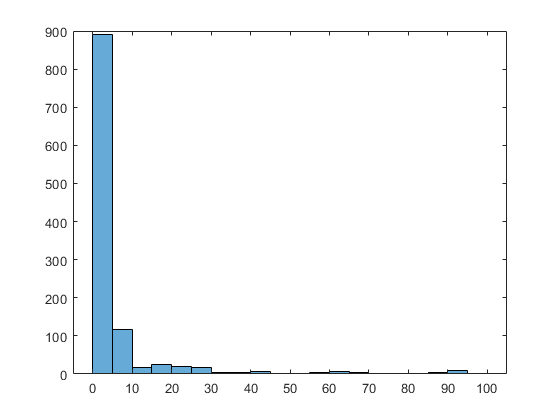

Document written


selectedFlux = filteredFluxes(selectedEFM, selectedRxns);
selectedFlux = selectedFlux';
writetable(table(model_irr.rxns(selectedRxns),selectedFlux,'VariableNames',{'Reactions','Flux'}), strcat(organism, dataFile, '_', string(selectedEFM), dataFileExt));

## D. Visualization

Follow these steps for each submodel SBML file that you wish to visualize.

- Make sure Cytoscape (v3 and above) is installed along with cy3sbml (app) and yFiles layout

- Open the SBML file using the cy3sbml app

- Import the style file supplied with this workflow (efmviz_style.xml) and apply this style. You can now see a network with three different types of nodes representing reactions, genes and metabolites and edges representing interaction between these molecule types. This is how your EFM looks!

- Set the layout using Layout -> yFiles Orthogonal layout. In our experience orthogonal layout works best for EFMs with 50-60 reactions. Beyond that, the EFM can be visualized, but will be difficult to interpret.

- (Optionally) Import the data file generated in step C.iv to map on the reaction edges. Use the R script (see below for details)

For running this step on several files, it is possible to automate the above mentioned operations - network manipulation and data mapping. This automation is done through R scripts that can be found at /core/R. 

Due to current unavailability of API for cy3sbml, unfortunately, the file import must be done manually through the GUI. Also, due to licensing issues, yFiles layout cannot be applied through the script and must be done in the GUI. We have tried our best to automate the network operations wherever possible. In the current version of cy3sbml, edges do not have an ID, so mapping the flux data on the edges is not straightforward. Therefore, the R script assigns an edge identifier (same as connected reactions) before mapping the data file from C.iv.

## REFERENCES

[1]

[2]